# Perform Safe Trajectory Tracking Control Using Robotics Manipulator Blocks

This example shows you how to use Simulink® with manipulator algorithm blocks to achieve safe trajectory tracking control of a simulated robot.

Both Robotics System Toolbox™ and Simscape Multibody™ are required to run this example. 

## Introduction

This example provides a model that implements a computed-torque controller with joint position and velocity feedback using manipulator algorithm blocks. The controller receives joint position and velocity information from a simulated robot (implemented using Simscape Multibody) and sends torque commands to drive the robot along a given joint trajectory. A planar object is placed in front of the robot so the end effector of the robot arm will collide with it when the trajectory is executed. Without any additional setup, the torque felt from colliding with the object can cause damage on the robot or the object. To achieve safe trajectory tracking, a trajectory scaling block is built to adjust the time stamp when assigning the desired motion to the controller. You may adjust some parameters and interact with the robot while the model is running and observe the effect on the simulated robot.

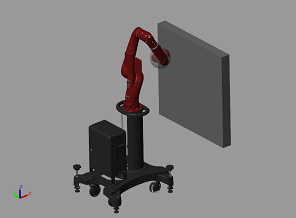

## Set Up Robot Model

This example uses a model of the Rethink Sawyer, a seven degree-of-freedom robot manipulator. Call [`importrobot`](docid:robotics_ref.bvlvwcs-1) to generate a [`rigidBodyTree`](docid:robotics_ref.bvan8uq-1) model from a description stored in a Unified Robot Description Format (URDF) file. Set the `DataFormat` and `Gravity` properties to be consistent with Simscape. The Simulink model accesses this robot model from the workspace in the simulation.

sawyer = importrobot('sawyer.urdf');
sawyer.removeBody('head');
sawyer.DataFormat = 'column';
sawyer.Gravity = [0, 0, -9.80665];

## Trajectory Generation

First, assign the start time and duration for the trajectory.

tStart = 0.5;
tDuration = 3;

Next, assign the initial and target configuration. `q0` is the initial configuration and `q1` is the target configuration.

q0 = [0; -1.18; 0; 2.18; 0; -1.0008; 3.3161];
q1 = zeros(7,1);

The following figures show the robot visualization of the initial configuration and the target configuration related to the location of the planar object. The planar object is placed so that the robot will collide to it during trajectory tracking.

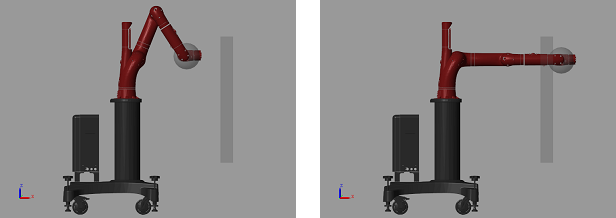

In the Simulink model, the [**Polynomial Trajectory**](docid:robotics_ref.mw_59e05d0a-835f-4d56-85a6-ee509b10771a) block computes the robot's position, velocity, and acceleration at any instant in the trajectory using a fifth-order polynomial.

## Simulink Model Overview

Next, open the Simulink model. The variables generated above are already stored in Simulink model workspace:

open_system('robotSafeTrajectoryTracking.slx');

The `robotSafeTrajectoryTracking` model implements a computed torque controller with trajectory scaling for safe trajectory tracking. There are three main subsystems in this model:

- Computed Torque Controller

- Trajectory Scaling and Desired Motion

- Simscape Multibody Model with Simple Contact Mechanics

On each time step, if the trajectory scaling switch is on, the modified time stamp is used for evaluating the desired joint position, velocity and acceleration. Then, the computed torque controller uses the manipulator blocks associated with the r`igidBodyTree` model to track the desired motion. The derived control input is fed into the Sawyer model in Simscape Multibody, where the planar object for interacting with the robot is included.

## Build Computed Torque Controller

For a manipulator with $$n $$ non-fixed joints, the system dynamics can be expressed as:


$$M(q)\ddot q +C(q,\dot q)\dot q+G(q) = u $$


where $$q $$, $$\dot q $$, $$\ddot q $$, $$\in R^n $$ are the position, velocity and acceleration of the generalized coordinate, $$u\in R^n $$ is the control input (torque), $$M(q) $$ is the joint space mass matrix, $$C(q,\dot q)\dot q $$ is the velocity product torque, $$G(q) $$ is the gravity torque. To track along a desired joint trajectory with desired position $$q_d $$, velocity $$\dot q_d $$ and acceleration $$\ddot q_d $$, the computed torque controller calculates the torque needed to obtain a given configuration and velocity, provided the robot dynamics variables $$M(q) $$, $$C(q,\dot q)\dot q $$, and $$G(q) $$. In Simulink, these variables can be easily derived using robotics manipulator blocks from Robotics System Toolbox to design the following computed torque controller:


$$ u = M(q)(\ddot q_d - K_d \dot q_e - K_p q_e) +  C(q,\dot q)\dot q+G(q) $$


where $$q_e = q - q_d $$ is the position error and $$\dot q_e = \dot q - \dot q_d $$ is the velocity error. With this controller input, the system dynamics becomes a second-order ODE:


$$\ddot q_e + K_d \dot q_e + K_p q_e = 0  $$


By choosing $$K_d $$ and $$K_p $$ properly, the tracking error $$q_e $$ will converge to zero when time approaches infinity.

The **Computed Torque Controller** subsystem is built using three robotics manipulator blocks: [`Joint Space Mass Matrix`](docid:robotics_ref.mw_515111a1-81c1-4281-8f61-b19fb96b4224),  [`Velocity Product Torque`](docid:robotics_ref.mw_ad15b2c9-0890-4a9d-97fc-42060d5f7670), and [`Gravity Torque`](docid:robotics_ref.mw_7749cf3c-9b53-433b-afb3-56e842210a75). Note that the associated [`rigidBodyTree`](docid:robotics_ref.bvan8uq-1) model, `sawyer`, is assigned in all those blocks, and the configuration and velocity need to be specified as column vectors.

open_system('robotSafeTrajectoryTracking/Computed Torque Controller');

Inside the **Computed Torque Controller**, there are two tunable parameters (indicated by colored blocks):

- Gain `Kp`: The proportional gain when correcting the robot configuration

- Gain `Kd`: The derivative gain when correcting the robot configuration

A standard way to determine the `Kp` and `Kd` is to calculate them as:


$$K_p = \omega_n^2 $$



$$K_d = 2\omega_n\xi $$


where $$\omega_n $$ and $$\xi $$ are the natural frequency and damping ratio of the second-order ODE. In this example, the default value of `Kp` and `Kd` are derived by setting the natural frequency and damping ratio as $$\omega_n=10 $$ and $$\xi=1 $$ to make the second-order ODE a critical damped system.

## Trajectory Scaling

There are two main blocks in this subsystem:

- Trajectory Scaling

- Desired Motion

**Trajectory Scaling** is the main block deployed for safe trajectory tracking in this example. At each time step $$t_i $$, the original time stamp is calculated as $$t_i = t_{i-1}+\Delta t $$. However, when the robot collides with an unexpected object, the increasing torque and deviance from the planned trajectory can be destructive for both the robot and the object. The main idea of trajectory scaling is to calculate the time stamp as $$t_i = t_{i-1}+f_s(q_d,\dot q_d,\ddot q_d, \tau_{mea})\Delta t $$ by introducing $$f_s(q_d,\dot q_d,\ddot q_d, \tau_{mea}) \in [-1, 1] $$, which is a function of the desired motion and measured torque $$\tau_{mea} $$. The function $$f_s() $$ controls the speed of the robot motion and is determined based on the interference felt by the robot. If the measured torques are greater than expected, $$f_s() $$ is decreased to make the robot slow down or even move backward until the desired torques are achieved. These values of $$f_s() $$ have the following effects on the robot's motion:

- $$f_s()>0 $$, the robot moves forward ($$f_s()=1 $$ is the normal speed).

- $$f_s()=0 $$, the robot stops.

- $$f_s()<0 $$, the robot moves backward.

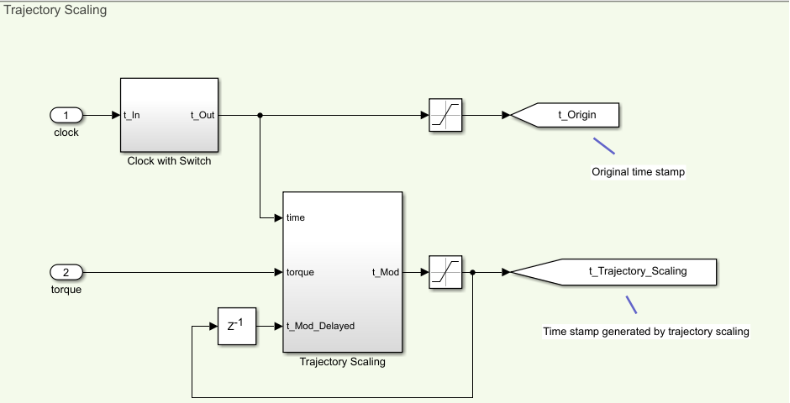

In the **Trajectory Scaling** block, it is required to estimate the external torque $$\hat\tau_{ext} = \tau_{mea} - \hat\tau $$ to calculate $$f_s() $$, where $$\tau_{mea} $$ is the measured torque from the Simscape model, and  $$\hat\tau $$ is the expected torque of the desired motion on the previous time stamp. In the External Torque Observer section of the model, the  [Inverse Dynamics](docid:robotics_ref.mw_0e10245c-236c-4e5c-9384-f921e9678488) block calculates the expected torque which is subtracted from the measure torque. Expected torque is: $$\hat\tau = M(q_d)(\ddot q_d) +  C(q_d,\dot q_d)\dot q_d+G(q_d) $$.

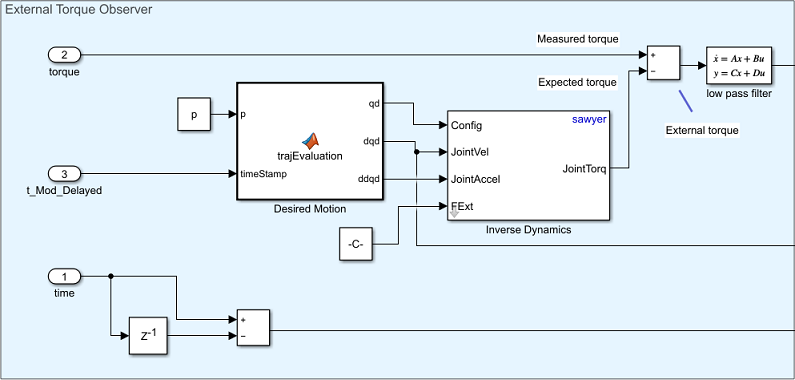

In the **Desired Motion** area, the output of the trajectory scaling algorithm is fed as an input to a **Polynomial Trajectory** block. This block compute a quintic polynomial trajectory given the known values of `q0` and `q1` and their boundary conditions of zero velocity and acceleration. It outputs the position, velocity, and acceleration: $$q_d(t) $$, $$\dot q_d(t) $$, and $$\ddot q_d(t) $$, which are fed to the **Computed Torque Controller** subsystem.

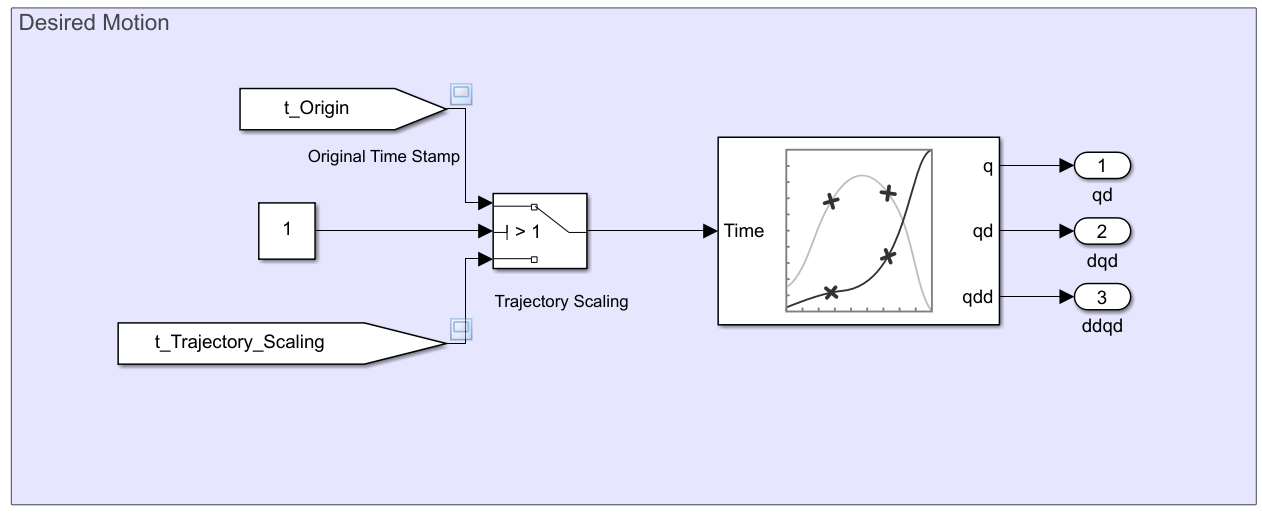

## Simscape Multibody Robot Model and Simple Contact Mechanics

The Simscape Multibody robot model is imported from the same `.urdf` file using `smimport`, where a set of torque actuators and sensors for joint torque, joint position and velocity are added. A contact mechanism block simulates the reaction force between the end effector and the obstacle as a sphere and a plane, where a simple linear spring-damper model is used.

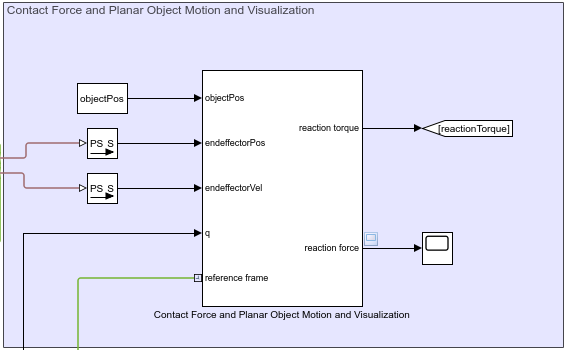

**Note:** The contact mechanism has only been implemented between the end effector and the planar object. Therefore, other parts of the robot arm may still pass through the obstacle.

## Run the Model

Run the model and observe the behavior of Sawyer in the robot simulator and interact with it. 

First, open the viewer by clicking on the scope icon shown below on the left of the Simscape model block. The scope displays signals including the joint torques, reaction contact force between the end effector and the planar object, and the time stamp for calculating desired motion for trajectory tracking.

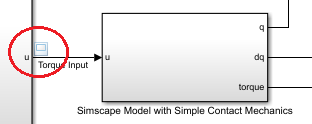

Toggle the trajectory scaling switch to "Off".

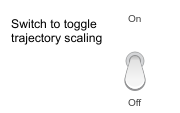

Use the following command or click **Run** to start the simulation. 

sim('robotSafeTrajectoryTracking.slx','StopTime','5');

Program interruption (Ctrl-C) has been detected.

You should see the arm collide with the object yielding high torque inputs and a large reaction force. Note in this case the original time stamp is used. Stop the simulation afterwards.

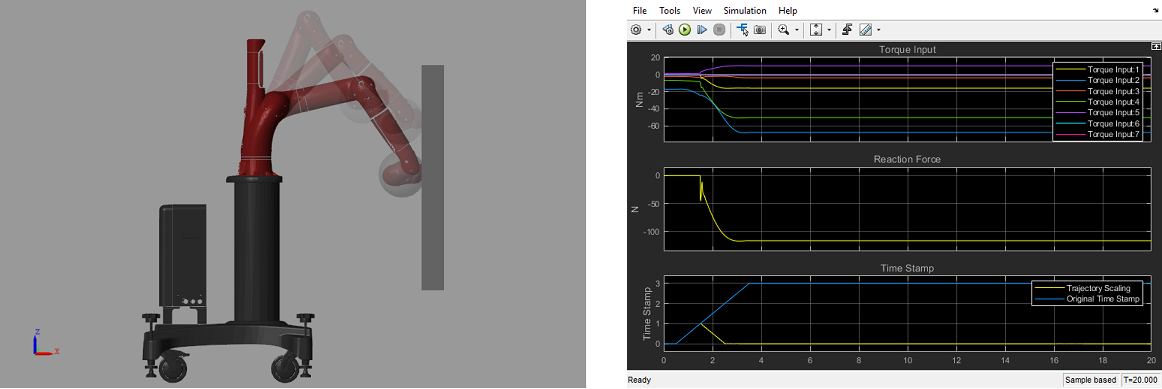

Now, toggle trajectory scaling switch to **On** and rerun the model.

Notice the differences in the computed torques and the reduced reaction force after the collision.

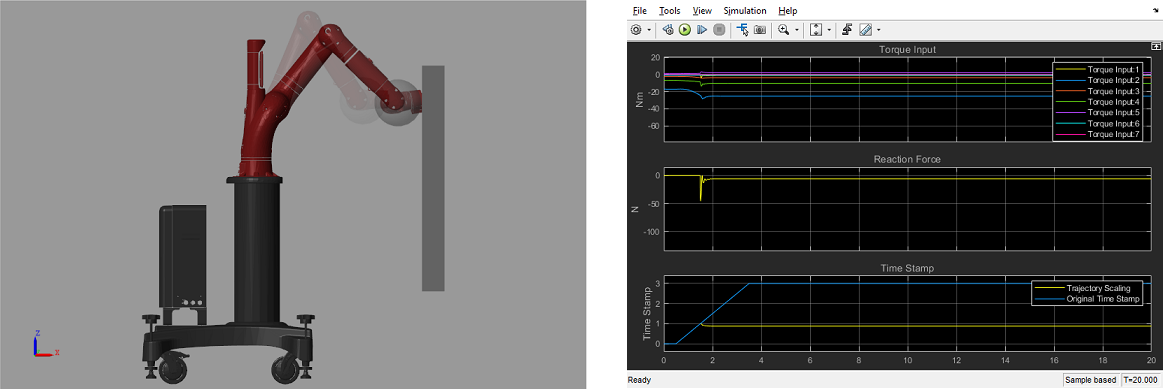

While the simulation is running, adjust the slider to move the object towards or away from the robot. The robot should react to its position while still trying to execute the trajectory safely.

## Summary

This example showed how to use robotics manipulator blocks in Simulink to design a computed torque controller, and integrate it with trajectory scaling and dynamic simulation in Simscape Multibody to achieve safe trajectory tracking. The resultant torque, reaction force, and time stamp demonstrated the capability of trajectory scaling for performing safe trajectory tracking.

*Copyright 2017-2021 The MathWorks, Inc.*